## Simulation variables

chan = "GaussianNoise";
SNRdB = 25;
txsite = "true";
rxsite = "true";
device = "true";
captime = 0;
usrpTriggerTime = 0;


## Set 5G  variables

 [carrier, pdsch, NHARQProcesses, rvSeq, codeRate, encodeDLSCH, decodeDLSCH] = genvar5g

carrier =   nrCarrierConfig with properties:

                NCellID: 1
      SubcarrierSpacing: 15
           CyclicPrefix: 'normal'
              NSizeGrid: 52
             NStartGrid: 0
                  NSlot: 0
                 NFrame: 0
    IntraCellGuardBands: [0×2 double]

   Read-only properties:
         SymbolsPerSlot: 14
       SlotsPerSubframe: 1
          SlotsPerFrame: 10


pdsch =   nrPDSCHConfig with properties:

                NSizeBWP: []
               NStartBWP: []
             ReservedPRB: {[1×1 nrPDSCHReservedConfig]}
              ReservedRE: []
              Modulation: '16QAM'
               NumLayers: 1
             MappingType: 'A'
        SymbolAllocation: [0 14]
                  PRBSet: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51]
              PRBSetType: 'VRB'
    VRBToPRBInterleaving: 0
           VRBBundleSize: 2
                     NID: []
                    RNTI: 1
                    DMRS: [1×1 nrPDSCHDMRSConfig]
              EnablePTRS: 0
                    PTRS: [1×1 nrPDSCHPTRSConfig]

   Read-only properties:
            NumCodewords: 1


ans =   nrPDSCHDMRSConfig with properties:

      DMRSConfigurationType: 1
         DMRSReferencePoint: 'CRB0'
          DMRSTypeAPosition: 2
     DMRSAdditionalPosition: 0
                 DMRSLength: 2
            CustomSymbolSet: []
                DMRSPortSet: []
                   NIDNSCID: []
                      NSCID: 0
    NumCDMGroupsWithoutData: 2
            DMRSDownlinkR16: 0

   Read-only properties:
                  CDMGroups: 0
                DeltaShifts: 0
           FrequencyWeights: [2×1 double]
                TimeWeights: [2×1 double]
    DMRSSubcarrierLocations: [6×1 double]
                 CDMLengths: [1 1]


NHARQProcesses = 1

rvSeq = 0

codeRate = 0.4785

encodeDLSCH =   nrDLSCH with properties:

    MultipleHARQProcesses: false
           TargetCodeRate: 0.4785
        LimitedBufferSize: 25344


decodeDLSCH =   nrDLSCHDecoder with properties:

        MultipleHARQProcesses: false
               TargetCodeRate: 0.4785
         TransportBlockLength: 5120
            LimitedBufferSize: 25344
        LDPCDecodingAlgorithm: 'Normalized min-sum'
                ScalingFactor: 0.7500
    MaximumLDPCIterationCount: 6


carrier =   nrCarrierConfig with properties:

                NCellID: 1
      SubcarrierSpacing: 15
           CyclicPrefix: 'normal'
              NSizeGrid: 52
             NStartGrid: 0
                  NSlot: 0
                 NFrame: 0
    IntraCellGuardBands: [0×2 double]

   Read-only properties:
         SymbolsPerSlot: 14
       SlotsPerSubframe: 1
          SlotsPerFrame: 10


pdsch =   nrPDSCHConfig with properties:

                NSizeBWP: []
               NStartBWP: []
             ReservedPRB: {[1×1 nrPDSCHReservedConfig]}
              ReservedRE: []
              Modulation: '16QAM'
               NumLayers: 1
             MappingType: 'A'
        SymbolAllocation: [0 14]
                  PRBSet: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51]
              PRBSetType: 'VRB'
    VRBToPRBInterleaving: 0
           VRBBundleSize: 2
                     NID: []
                    RNTI: 1
                    DMRS: [1×1 nrPDSCHDMRSConfig]
              EnablePTRS: 0
                    PTRS: [1×1 nrPDSCHPTRSConfig]

   Read-only properties:
            NumCodewords: 1


NHARQProcesses = 1

rvSeq = 0

codeRate = 0.4785

encodeDLSCH =   nrDLSCH with properties:

    MultipleHARQProcesses: false
           TargetCodeRate: 0.4785
        LimitedBufferSize: 25344


decodeDLSCH =   nrDLSCHDecoder with properties:

        MultipleHARQProcesses: false
               TargetCodeRate: 0.4785
         TransportBlockLength: 5120
            LimitedBufferSize: 25344
        LDPCDecodingAlgorithm: 'Normalized min-sum'
                ScalingFactor: 0.7500
    MaximumLDPCIterationCount: 6


## HARQ Management

harqEntity = HARQEntity(0:NHARQProcesses-1,rvSeq,pdsch.NumCodewords);

## Channel config

nTxAnts = 1;
nRxAnts = 1;

% Check that the number of layers is valid for the number of antennas
if pdsch.NumLayers > min(nTxAnts,nRxAnts)
    error("The number of layers ("+string(pdsch.NumLayers)+") must be smaller than min(nTxAnts,nRxAnts) ("+string(min(nTxAnts,nRxAnts))+")")
end

channel = nrTDLChannel;
channel.DelayProfile = "TDL-E";
channel.NumTransmitAntennas = nTxAnts;
channel.NumReceiveAntennas = nRxAnts;

ofdmInfo = nrOFDMInfo(carrier);
channel.SampleRate = ofdmInfo.SampleRate;


constPlot = comm.ConstellationDiagram;                                          % Constellation diagram object
constPlot.ReferenceConstellation = getConstellationRefPoints(pdsch.Modulation); % Reference constellation values
constPlot.EnableMeasurements = 1;                                               % Enable EVM measurements

% Initial timing offset
offset = 0;

longwave = 0.00001+0.00001i;
rxBit = 0;

estChannelGrid = getInitialChannelEstimate(channel,carrier);
newPrecodingWeight = getPrecodingMatrix(pdsch.PRBSet,pdsch.NumLayers,estChannelGrid);

% Generate PDSCH indices info, which is needed to calculate the transport
% block size
[pdschIndices,pdschInfo] = nrPDSCHIndices(carrier,pdsch);

% Calculate transport block sizes
Xoh_PDSCH = 0;
trBlkSizes = nrTBS(pdsch.Modulation,pdsch.NumLayers,numel(pdsch.PRBSet),pdschInfo.NREPerPRB,codeRate,Xoh_PDSCH);
bitlen = trBlkSizes/8;

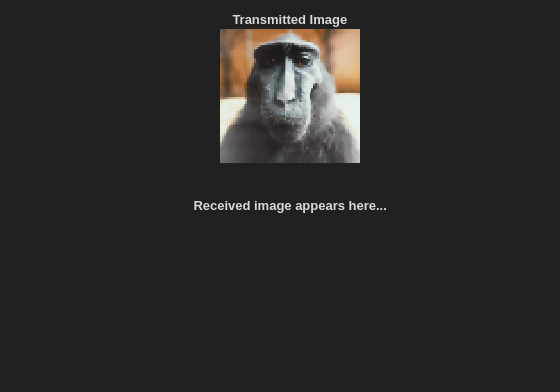

% Setup handle for image plot
if ~exist('imFig','var') || ~ishandle(imFig) %#ok<SUSENS> 
    imFig = figure;
    imFig.NumberTitle = 'off';
    imFig.Name = 'Image Plot';
    imFig.Visible = 'off';
else
    clf(imFig); % Clear figure
    imFig.Visible = 'off';
end


% Input an image file and convert to binary stream
fileTx = 'monkey.png';                   % Image file name
fData = imread(fileTx);                          % Read image data from file
scale = 0.285;                    % Image scaling factor
origSize = size(fData);                          % Original input image size
scaledSize = max(floor(scale.*origSize(1:2)),1); % Calculate new image size
heightIx = min(round(((1:scaledSize(1))-0.5)./scale+0.5),origSize(1));
widthIx = min(round(((1:scaledSize(2))-0.5)./scale+0.5),origSize(2));
fData = fData(heightIx,widthIx,:);               % Resize image
imsize = size(fData);                            % Store new image size
txImage = fData(:);
padZeros = bitlen-mod(length(txImage),bitlen);
txData = [txImage;zeros(padZeros,1)];
txDataBits = double(int2bit(txData,8,false));

totalNoSlots = (size(txDataBits, 1)/trBlkSizes);  

% Plot transmit image
imFig.Visible = 'on';
subplot(211);
imshow(fData);
title('Transmitted Image');
subplot(212);
title('Received image appears here...');
set(gca,'Visible','off');

set(findall(gca, 'type', 'text'), 'visible', 'on');





slstr = 1;
slend = trBlkSizes;
for nSlot = 0:totalNoSlots-1
     carrier.NSlot = nSlot;

        data = txDataBits(slstr:slend,1);
        slstr = slstr + trBlkSizes;
        slend = slend + trBlkSizes;


    [txWaveform, waveformInfo, trBlk, trBlkSizes] = TransmitterEntity2(carrier, pdsch, encodeDLSCH, harqEntity, newPrecodingWeight, codeRate, data, nTxAnts, decodeDLSCH);

    chInfo = info(channel);
    maxChDelay = 0;%chInfo.MaximumChannelDelay;
    txWaveform = [zeros(maxChDelay,size(txWaveform,2));txWaveform; zeros(maxChDelay,size(txWaveform,2))];

    if strcmpi(chan,"OverTheAir")
        longwave = cat(1, longwave,txWaveform);
    elseif strcmpi(chan,"GaussianNoise")
        [txWaveform2,pathGains,sampleTimes] = channel(txWaveform);
        noise = generateAWGN(SNRdB,nRxAnts,waveformInfo.Nfft,size(txWaveform2));
        txWaveform2 = txWaveform2 + noise;
        longwave = cat(1, longwave,txWaveform2);
    else
        longwave = cat(1, longwave,txWaveform);
    end
    

    
   
end  

## Device setup

if device == 'usrp'
    tx = comm.SDRuTransmitter(...
               Platform = "B200", ...
              SerialNum = "3293CEA", ...
              CenterFrequency = 2400000000, ...
              InterpolationFactor = 256, ...
              MasterClockRate = channel.SampleRate, ...
              Gain = 20);

    rx = comm.SDRuReceiver(...
              Platform ="B200", ...
              SerialNum ="3293CEA", ...
              CenterFrequency =2400000000, ...
              MasterClockRate =channel.SampleRate, ...
              DecimationFactor = 256, ...
              OutputDataType = 'double' );
rx.Gain = 70;
rx.EnableBurstMode = false;
% Provide trigger time
tx.EnableTimeTrigger = true;
tx.TriggerTime = usrpTriggerTime;
elseif device == 'pluto'
    tx = comm.SDRuTransmitter(...
              Platform = "B200", ...
              SerialNum = "3293CEA", ...
              CenterFrequency = 2400000000, ...
              InterpolationFactor = 256, ...
              MasterClockRate = channel.SampleRate, ...
              Gain = 20);

    rx = comm.SDRuReceiver(...
              Platform ="B200", ...
              SerialNum ="3293CEA", ...
              CenterFrequency =2400000000, ...
              MasterClockRate =channel.SampleRate, ...
              DecimationFactor = 256, ...
              OutputDataType = 'double' );
    rx.Gain = 70;
    rx.EnableBurstMode = false;
    % Provide trigger time
    tx.EnableTimeTrigger = true;
    tx.TriggerTime = usrpTriggerTime;
end


if strcmpi(chan,"OverTheAir")
    tx(longwave);
else
    chInfo = info(channel);
    maxChDelay = 20000;%chInfo.MaximumChannelDelay;
    longwave = [zeros(maxChDelay,size(longwave,2));longwave; zeros(maxChDelay,size(longwave,2))];
end

if strcmpi(chan,"OverTheAir")
    rxWaveform2 = capture(rx,captime,'seconds');
else
    rxWaveform2 = longwave;
end

    
    rxWaveform = rxWaveform2;
    precodingWeights = newPrecodingWeight;
    dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
    dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch);
    [pdschIndices,pdschInfo] = nrPDSCHIndices(carrier,pdsch);


    %% Timing Synchronization
    [t,mag] = nrTimingEstimate(carrier,rxWaveform,dmrsIndices,dmrsSymbols);
    offset = hSkipWeakTimingOffset(offset,t,mag);

    [t2,mag2] = nrTimingEstimate(carrier,rxWaveform,dmrsIndices,dmrsSymbols);
    offset2 = hSkipWeakTimingOffset(offset,t2,mag2);
    
    
    pakoff = ((totalNoSlots*15370)-15370);

    if offset >= 100
        rxWaveform = rxWaveform(1+offset-pakoff-300:end,:);
    else
        rxWaveform = rxWaveform(1:end,:);
    end
    



statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

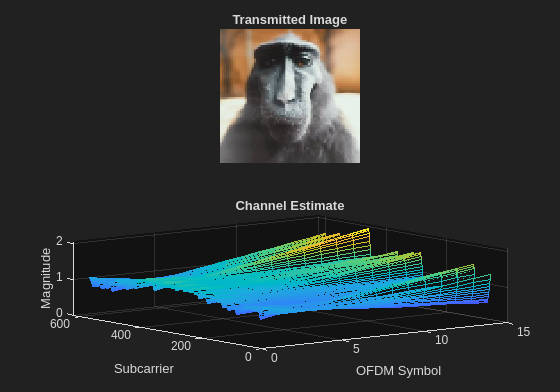

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

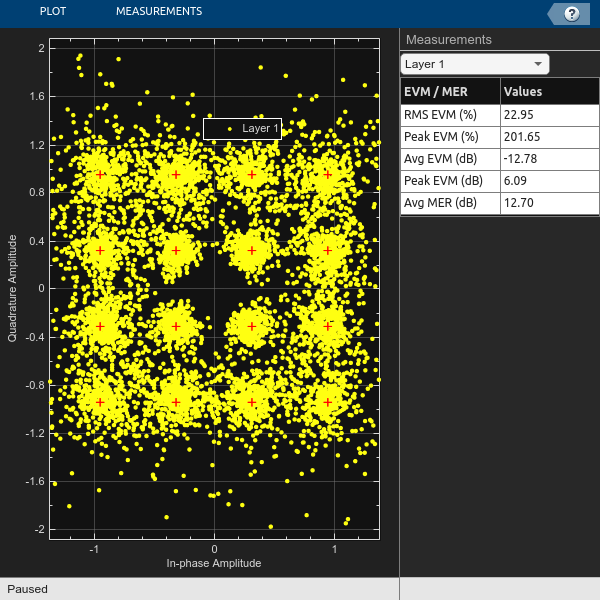


srec = 1;
erec = 15771;
for nSlot = 0:totalNoSlots-1
     carrier.NSlot = nSlot;
      

     decWave = rxWaveform(srec:erec,1);

     srec = srec + 15371;
     erec = erec + 15371;
    

    %%decWave = nrTimingEstimate(waveform,nrb,scs,initialNSlot,refInd,refSym)
    [decbits, statusReport, pdschEq] = RecieverEntity(carrier, pdsch, decodeDLSCH, harqEntity, decWave, offset, newPrecodingWeight, trBlkSizes);

    statusReport

    constPlot.ChannelNames = "Layer "+(pdsch.NumLayers:-1:1);
    constPlot.ShowLegend = true;
    % Constellation for the first layer has a higher SNR than that for the
    % last layer. Flip the layers so that the constellations do not mask
    % each other.
    constPlot(fliplr(pdschEq));
    
    rxBit = cat(1, rxBit, decbits);
end

rxBit(1) = []

rxBit = 143440×1 int8 column vector
   1
   1
   1
   0
   0
   1
   1
   0
   0
   1


if rxBit == txDataBits
    status = "succes"
end

status = "succes"

 % Reshape such that each column length has bits equal to msduLength*8
    rxData = reshape(rxBit,trBlkSizes,[]);

   

    decData = bit2int(reshape(rxData(:),8,[]),8,false)';

    % Append NaNs to fill any missing image data
    if length(decData)<length(txImage)
        numMissingData = length(txImage)-length(decData);
        decData = [decData;NaN(numMissingData,1)];
    else
        decData = decData(1:length(txImage));
    end

    % Recreate image from received data
    fprintf('\nConstructing image from received data.\n');


Constructing image from received data.


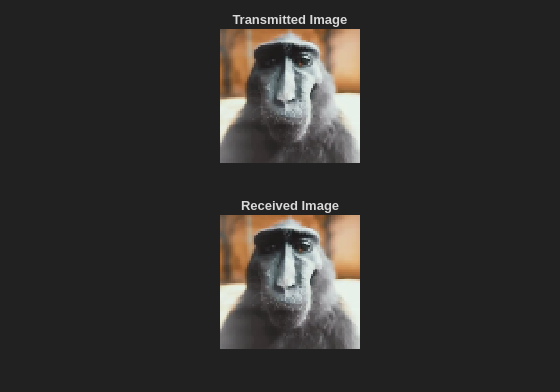

    receivedImage = uint8(reshape(decData,imsize));
    % Plot received image
    if exist('imFig','var') && ishandle(imFig) % If Tx figure is open
        figure(imFig); subplot(212);
    else
        figure; subplot(212);
    end
    imshow(receivedImage);
    title(sprintf('Received Image'));

## USRP release

release(tx);
fprintf('Recieving stopped.\n')

Recieving stopped.


release(rx);
fprintf('Transmission stopped.\n')

Transmission stopped.


## Local Functions

function noise = generateAWGN(SNRdB,nRxAnts,Nfft,sizeRxWaveform)
% Generate AWGN for a given value of SNR in dB (SNRDB), which is the
% receiver SNR per RE and antenna, assuming the channel does
% not affect the power of the signal. NRXANTS is the number of receive
% antennas. NFFT is the FFT size used in OFDM demodulation. SIZERXWAVEFORM
% is the size of the receive waveform used to calculate the size of the
% noise matrix.

    % Normalize noise power by the IFFT size used in OFDM modulation, as
    % the OFDM modulator applies this normalization to the transmitted
    % waveform. Also normalize by the number of receive antennas, as the
    % channel model applies this normalization to the received waveform by
    % default. The SNR is defined per RE for each receive antenna (TS
    % 38.101-4).
    SNR = 10^(SNRdB/10); % Calculate linear noise gain
    N0 = 1/sqrt(2.0*nRxAnts*double(Nfft)*SNR);
    noise = N0*complex(randn(sizeRxWaveform),randn(sizeRxWaveform));
end

function wtx = getPrecodingMatrix(PRBSet,NLayers,hestGrid)
% Calculate precoding matrix given an allocation and a channel estimate
    
    % Allocated subcarrier indices
    allocSc = (1:12)' + 12*PRBSet(:).';
    allocSc = allocSc(:);
    
    % Average channel estimate
    [~,~,R,P] = size(hestGrid);
    estAllocGrid = hestGrid(allocSc,:,:,:);
    Hest = permute(mean(reshape(estAllocGrid,[],R,P)),[2 3 1]);
    
    % SVD decomposition
    [~,~,V] = svd(Hest);
    
    wtx = V(:,1:NLayers).';
    wtx = wtx/sqrt(NLayers); % Normalize by NLayers
end

function estChannelGrid = getInitialChannelEstimate(channel,carrier)
% Obtain an initial channel estimate for calculating the precoding matrix.
% This function assumes a perfect channel estimate

    % Clone of the channel
    chClone = channel.clone();
    chClone.release();

    % No filtering needed to get channel path gains
    chClone.ChannelFiltering = false;    
    
    % Get channel path gains
    [pathGains,sampleTimes] = chClone();
    
    % Perfect timing synchronization
    pathFilters = getPathFilters(chClone);
    offset = nrPerfectTimingEstimate(pathGains,pathFilters);
    
    % Perfect channel estimate
    estChannelGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);
end

function refPoints = getConstellationRefPoints(mod)
% Calculate the reference constellation points for a given modulation
% scheme.
    switch mod
        case "QPSK"
            nPts = 4;
        case "16QAM"
            nPts = 16;
        case "64QAM"
            nPts = 64;
        case "256QAM"
            nPts = 256;            
    end
    binaryValues = int2bit(0:nPts-1,log2(nPts));
    refPoints = nrSymbolModulate(binaryValues(:),mod);
end

function estChannelGrid = precodeChannelEstimate(estChannelGrid,W)
% Apply precoding matrix W to the last dimension of the channel estimate.

    % Linearize 4-D matrix and reshape after multiplication
    K = size(estChannelGrid,1);
    L = size(estChannelGrid,2);
    R = size(estChannelGrid,3);
    estChannelGrid = reshape(estChannelGrid,K*L*R,[]);
    estChannelGrid = estChannelGrid*W;
    estChannelGrid = reshape(estChannelGrid,K,L,R,[]);

end
